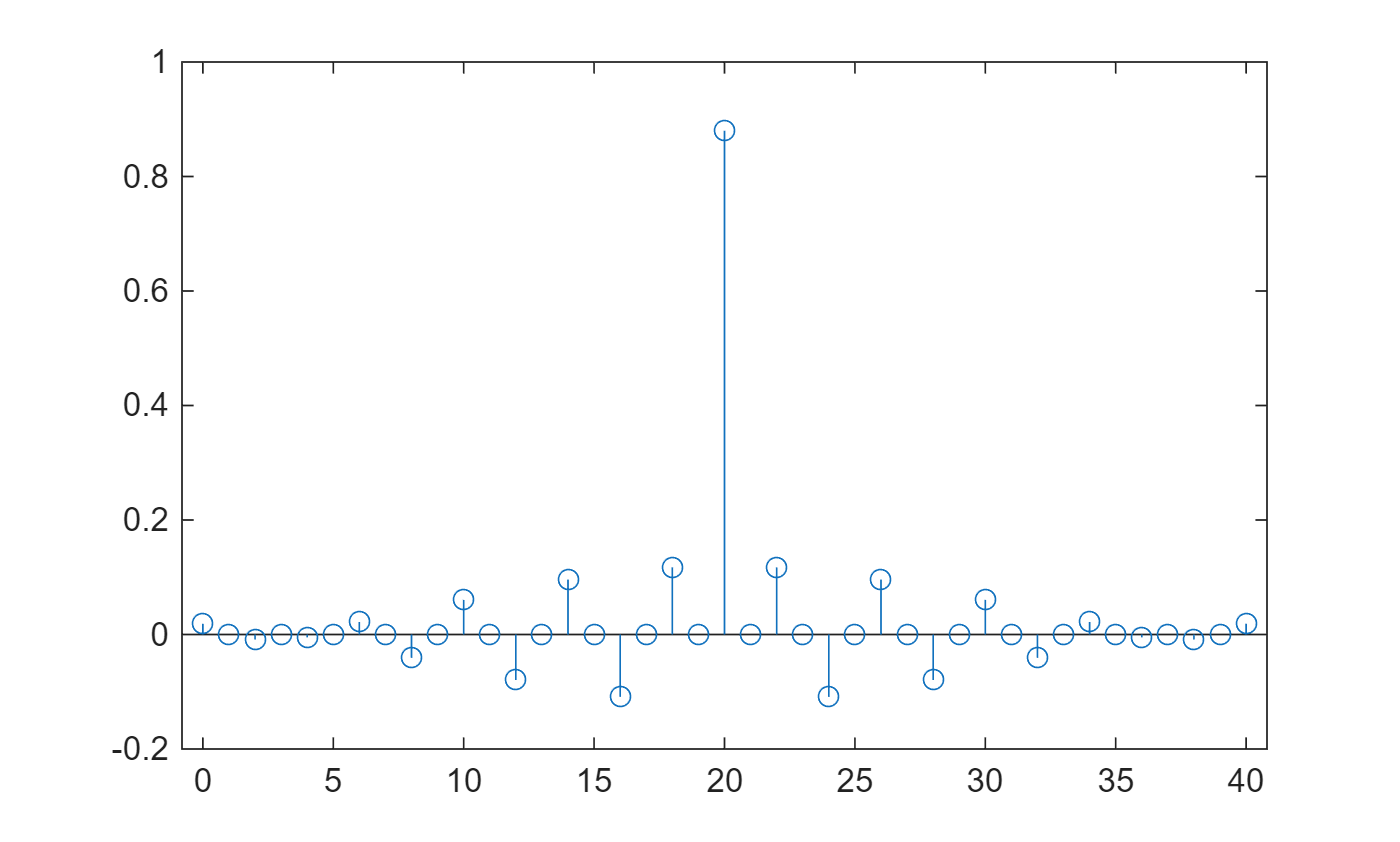

N_taps = 41; F_L = 440; F_H = 560; F_s = 2e3;

[M, K] = MK_values(N_taps);

n = [-K:K];

omega_H = (2*pi*F_H)/F_s; omega_L = (2*pi*F_L)/F_s;

h_bs = FIR_fourier("BS", n, omega_H, omega_L);

stem(0:M, h_bs)

h_bs(19+4)

ans = 0.1172

h_bs(19+8)

ans = 0.0960

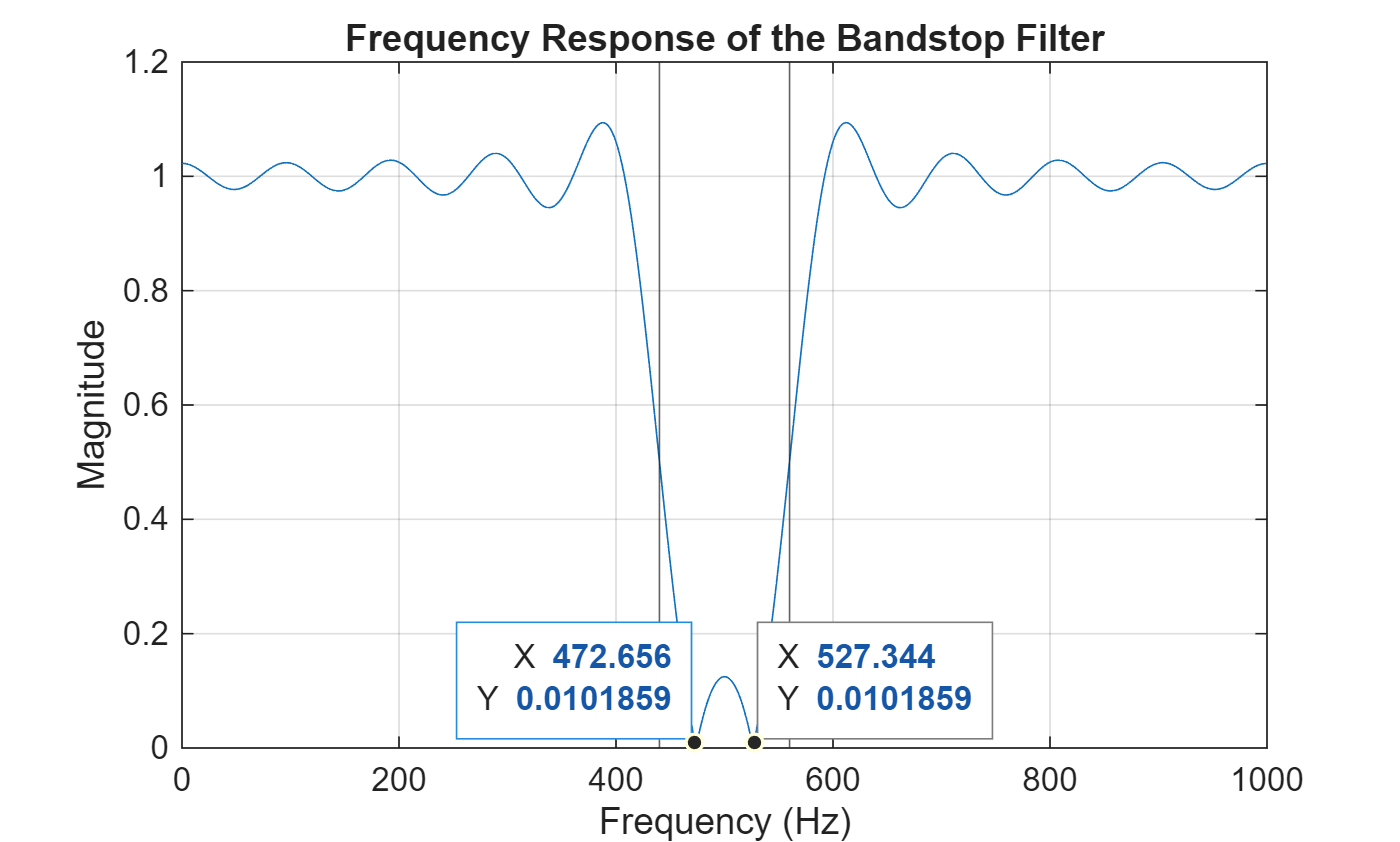

[h, f] = freqz(h_bs, 1, 1024, F_s);

figure;
plot(f, abs(h));
xlabel('Frequency (Hz)')
ylabel('Magnitude');
title('Frequency Response of the Bandstop Filter');
xline([F_L F_H]);
grid on;
 
ax = gca;
chart = ax.Children(3);
datatip(chart,559.6,0.000494);
datatip(chart,440.4,0.000494,"Location","northwest");

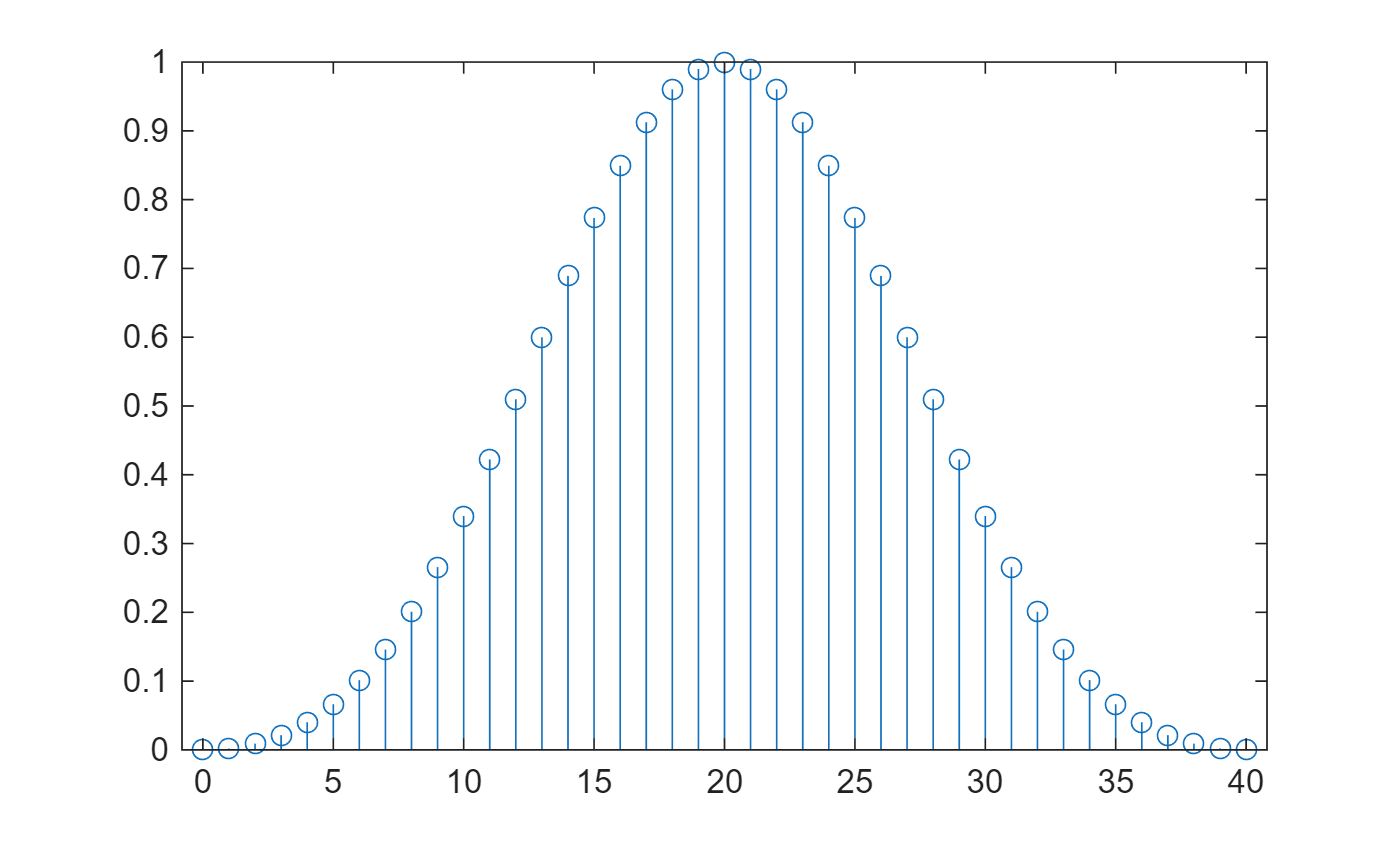


hDataTip = findobj(gca,"DataIndex",420);
set(hDataTip,"X",440.4,"Y",0.5058,"Location","northwest");
hDataTip = findobj(gca,"DataIndex",606);
set(hDataTip,"X",559.6,"Y",0.5058);
w_blackman = FIR_window("Blackman", 0:M, M);
stem(0:M, w_blackman)

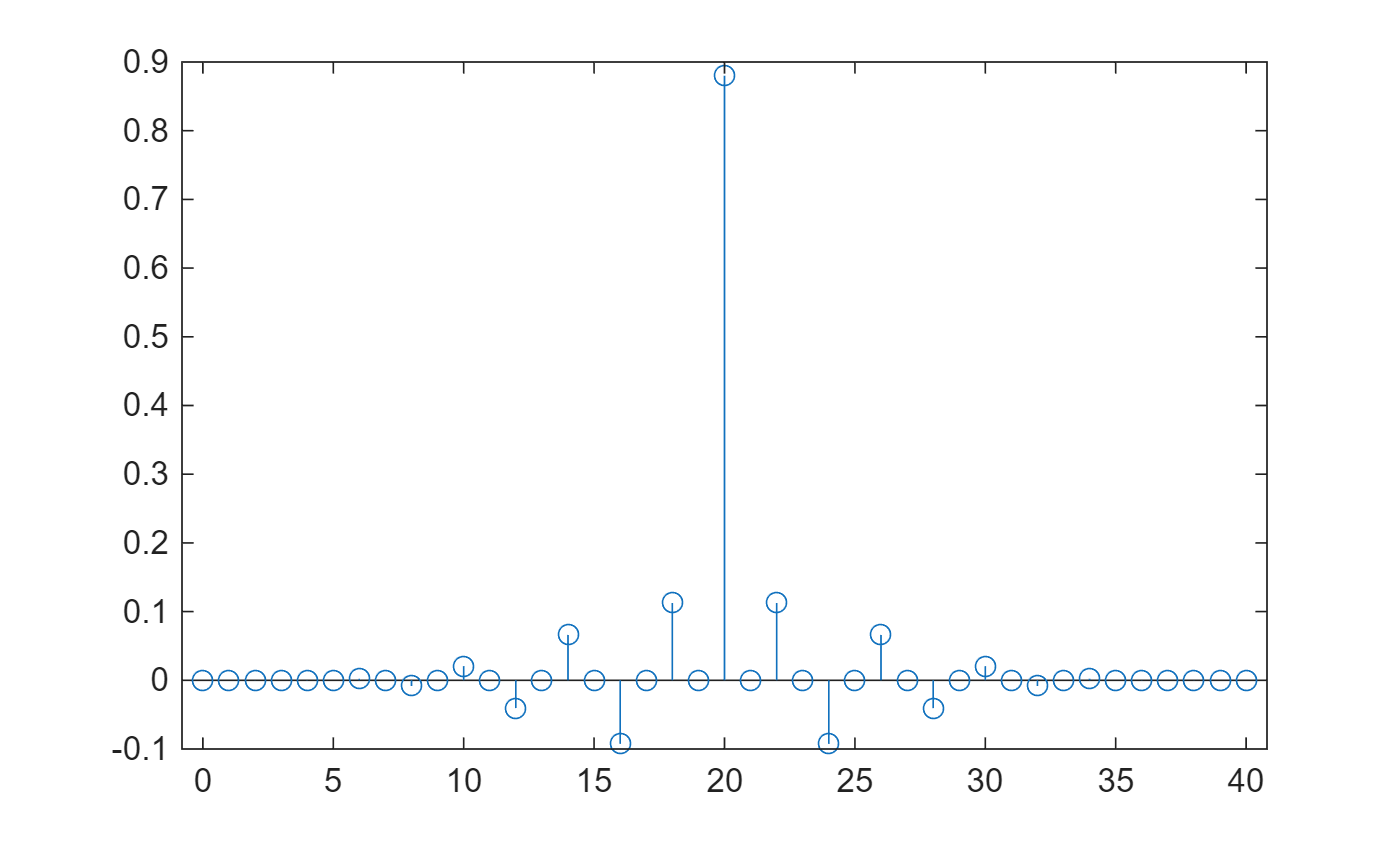


h_w = h_bs.*w_blackman;

stem(0:M, h_w)

h_bs(19+4)

ans = 0.1172

h_bs(19+8)

ans = 0.0960

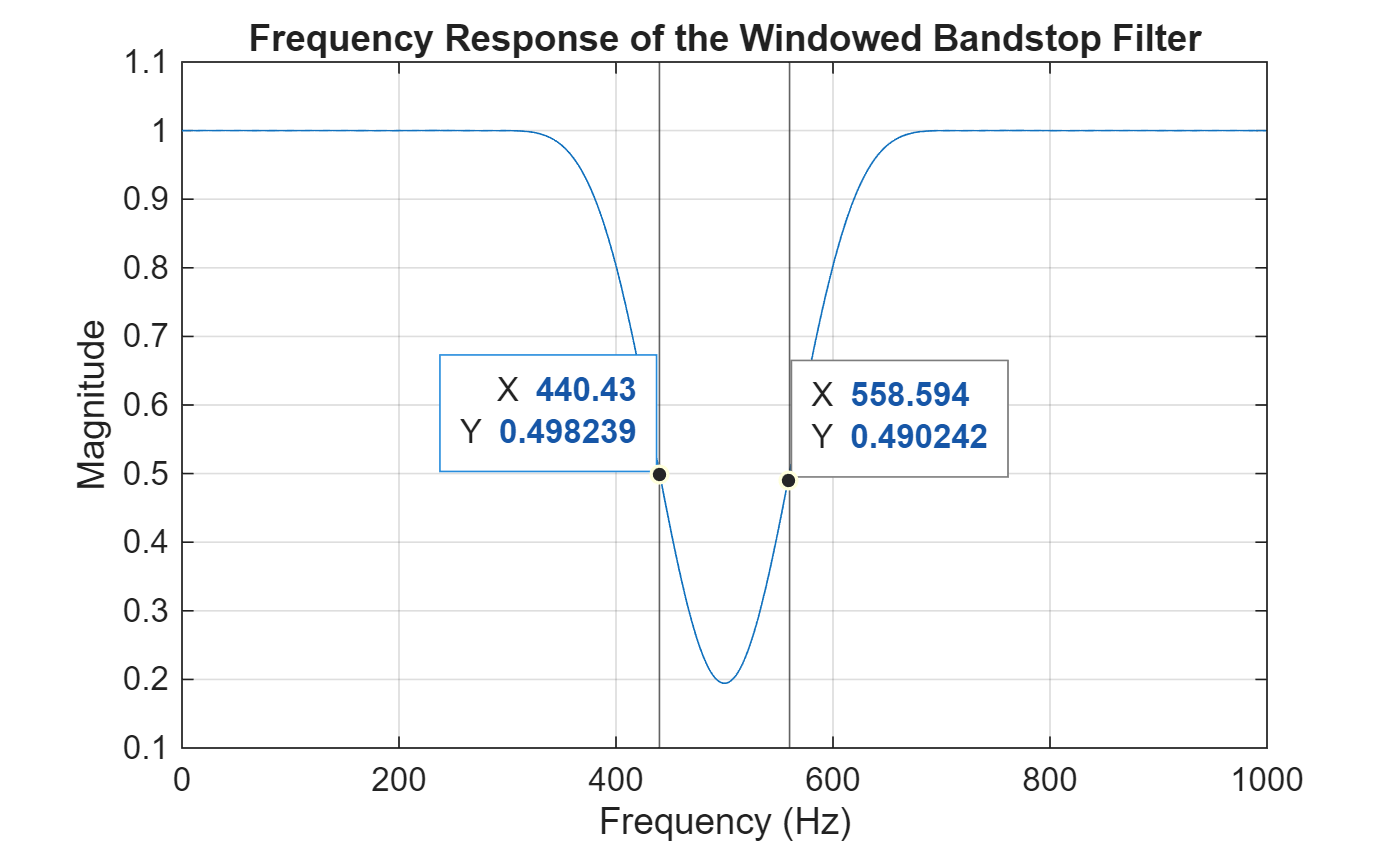

[h, f] = freqz(h_w, 1, 1024, F_s);

figure;
plot(f, abs(h));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Response of the Windowed Bandstop Filter');
xline([F_L F_H]);
grid on;

ax2 = gca;
chart2 = ax2.Children(3);
datatip(chart2,560.5,0.4937);
datatip(chart2,440.4,0.5018,"Location","northwest");

t = time_vec(F_s, N_taps);
x_1 = 1.5*cos(2*pi*200*t); x_2 = 0.4*cos(2*pi*500*t); x_3 = 1.8*cos(2*pi*800*t);

%have to wait for the signal to reach steady state before checking,
%so therefore, the real amplitude value is at the end of the vector length.
x_1filtered = filter(h_w, 1, x_1);
max(x_1filtered(end))

ans = 1.4999

x_2filtered = filter(h_w, 1, x_2);
max(x_2filtered(end))

ans = 0.0777

x_3filtered = filter(h_w, 1, x_3);
max(x_3filtered(end))

ans = 1.7999

## 4.

clear; clc;
